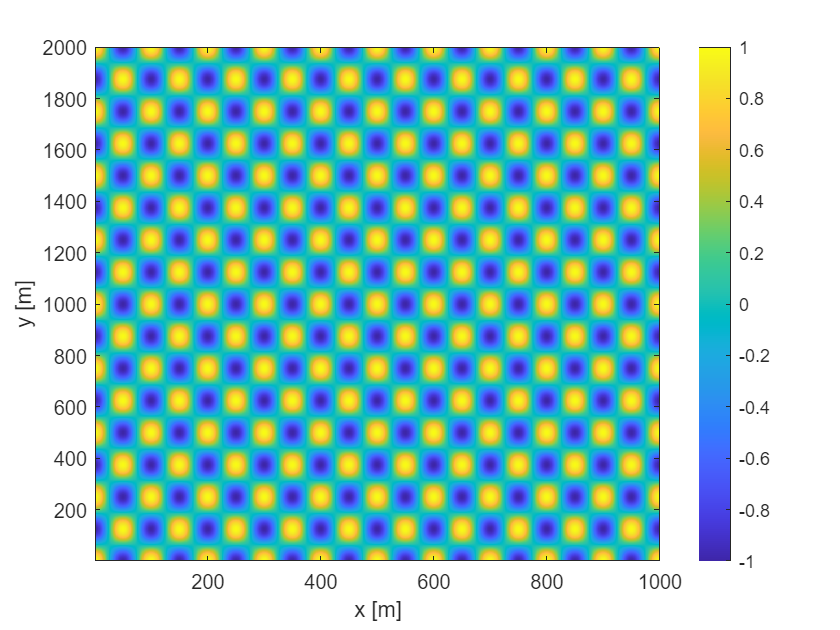

xx = 1:1000;
yy = 1:2000;

[x,y]=meshgrid(xx,yy);

kx0 = 0.01;
ky0 = 0.004;

w = cos(x*2*pi*kx0).*cos(y*2*pi*ky0);

figure(1);clf
imagesc(xx,yy,w);
set(gca,'ydir','no');
xlabel('x [m]');
ylabel('y [m]');
colorbar;

% first k_x = [0:N-1]/\deltax

M = length(xx);
N = length(yy);

dx = 1;
k_x = (0:M-1)/dx/M;
dy = 1;
k_y = (0:N-1)/dx/N;


X = fft(w')';

Gx = (1/M/dx)*X(:,2:M/2).* conj(X(:,2:M/2));
k_x = k_x(2:M/2);

figure(2);clf

loglog(k_x,Gx(10,:));

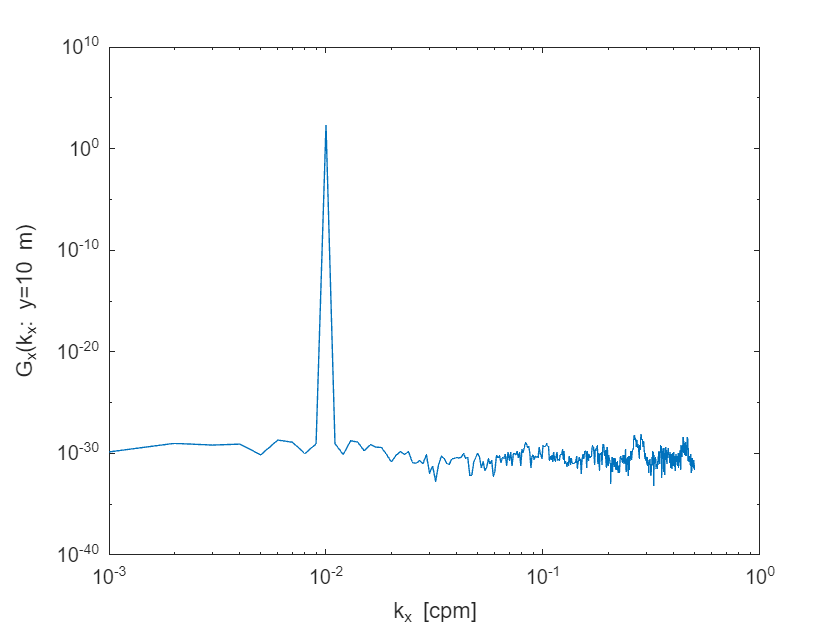

xlabel('k_x [cpm]');
ylabel('G_x(k_x: y=10 m)');

in = find(k_x>kx0);
in = in(1)-1;
figure(3); clf;
plot(y,Gx(:,in));

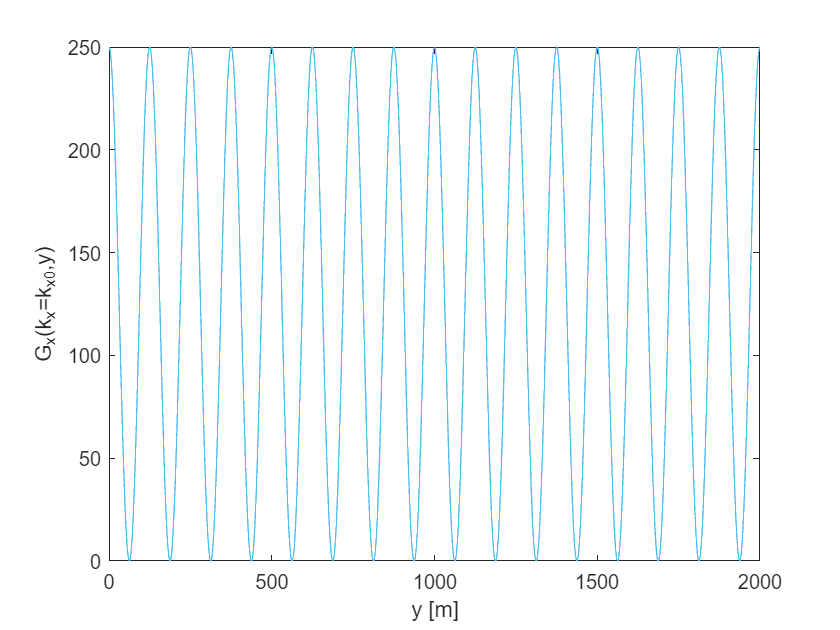

xlabel('y [m]');
ylabel('G_x(k_x=k_{x0},y)');

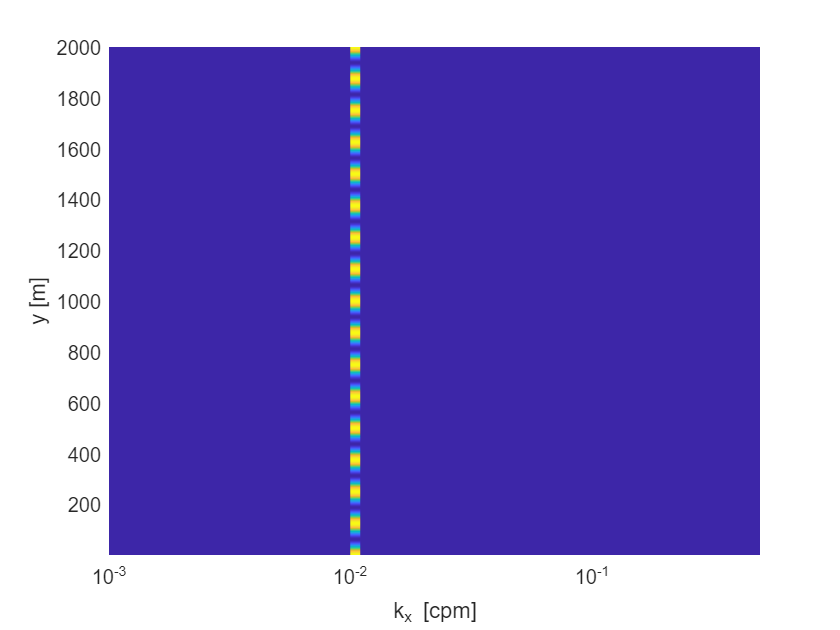

figure(4);

pcolor(k_x,yy,real(Gx));shading flat;
set(gca,'xscale','log');
xlabel('k_x [cpm]');
ylabel('y [m]');

XY = fft(fft(w')');
k_x = (0:M-1)/dx/M;
k_y = (0:N-1)/dx/N;

GXY = (1/M/dx)*(1/N/dy)*XY(2:N/2,2:M/2).* conj(XY(2:N/2,2:M/2));
k_y = k_y(2:N/2);
k_x = k_x(2:M/2);

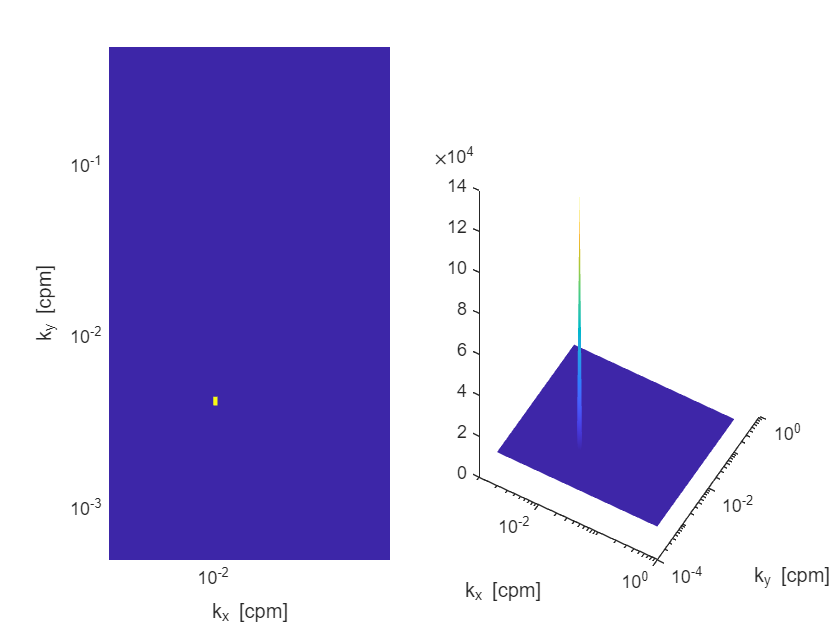

figure(5);clf
subplot(1,2,1);

pcolor(k_x,k_y,real(GXY));shading flat;
set(gca,'xscale','log','yscale','log')
xlabel('k_x [cpm]');
ylabel('k_y [cpm]');

subplot(1,2,2);

surface(k_x,k_y,real(GXY));shading interp;
set(gca,'xscale','log','yscale','log')
xlabel('k_x [cpm]');
ylabel('k_y [cpm]');
view(30,30);

[pxx, kxs] = pwelch(w', [], [], [], 1/dx);
pxx = pxx';
[pxxyy, kys] = pwelch(pxx, [], [], [], 1/dy);

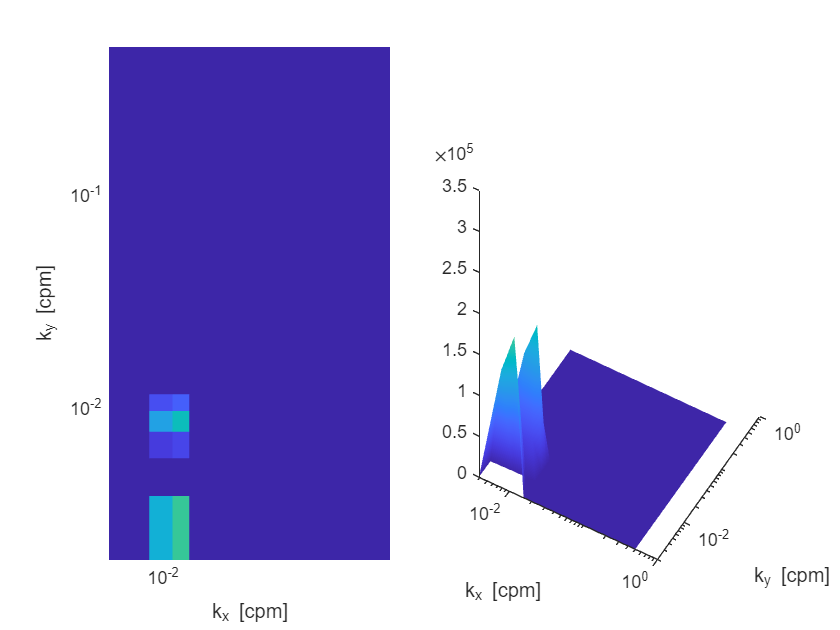

figure(6);clf
subplot(1,2,1);

pcolor(kxs,kys,pxxyy);shading flat;
set(gca,'xscale','log','yscale','log')
xlabel('k_x [cpm]');
ylabel('k_y [cpm]');

subplot(1,2,2);

surface(kxs,kys,pxxyy);shading interp;
set(gca,'xscale','log','yscale','log')
xlabel('k_x [cpm]');
ylabel('k_y [cpm]');
view(30,30);

Pwosa = pwelch2(w, [1000, 500], 0.6, @(x) hamming(x));
k_x = (0:M-1)/dx/M;
k_y = (0:N-1)/dx/N;

k_y = k_y(2:N/2);
k_x = k_x(2:M/2);
Pwosa_half = Pwosa(2:N/2, 2:M/2);

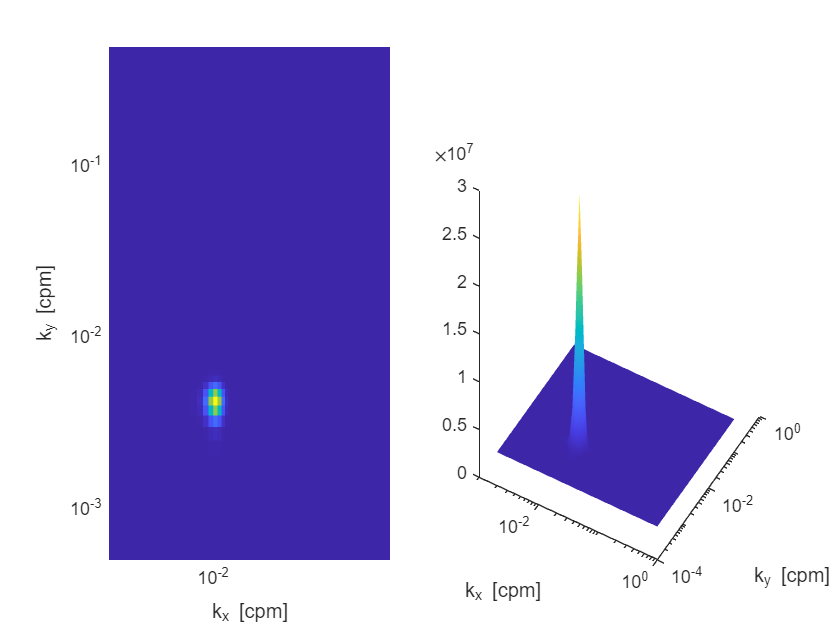

figure(5);clf
subplot(1,2,1);

pcolor(k_x,k_y,real(Pwosa_half));shading flat;
set(gca,'xscale','log','yscale','log')
xlabel('k_x [cpm]');
ylabel('k_y [cpm]');

subplot(1,2,2);

surface(k_x,k_y,real(Pwosa_half));shading interp;
set(gca,'xscale','log','yscale','log')
xlabel('k_x [cpm]');
ylabel('k_y [cpm]');
view(30,30);